# Modelagem dos motores e Controle de velocidade

clear 
data = readtable("modelagem_motor.txt")

data = 80×5 table
      t       u_ml    theta_ml    u_mr    theta_mr
    ______    ____    ________    ____    ________

    0.0001    100           0     100           0 
    0.0101    100      0.0224     100       0.015 
    0.0201    100      0.1346     100      0.1197 
    0.0301    100      0.3291     100      0.3142 
    0.0401    100      0.6059     100       0.576 
    0.0501    100      0.9275     100      0.8901 
    0.0601    100      1.3015     100      1.2566 
    0.0701    100      1.7129     100      1.6606 
    0.0801    100      2.1468     100      2.0869 
    0.0901    100      2.6105     100      2.5357 
    0.1001    100      3.0892     100       3.007 
    0.1101    100      3.5904     100      3.5006 
    0.1201    100      4.1065     100      3.9943 
    0.1301    100      4.6301     100      4.5

#### Tempo de amostragem

- Devemos ter certeza que os calculos não atrapalharam o período de amostragem 

ts = mean(diff(data.t))

ts = 0.0100

## Motor Esquerdo

data_ident_ml = iddata(gradient(data.theta_ml, data.t), data.u_ml, ts)

data_ident_ml =

Time domain data set with 80 samples.
Sample time: 0.0100013 seconds        
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties


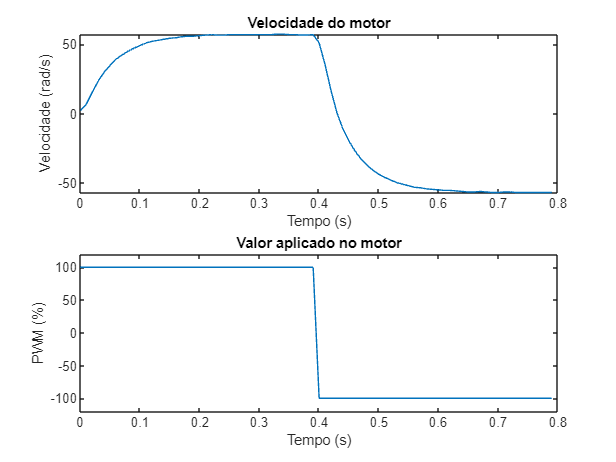

omega_ml = gradient(data.theta_ml, data.t); % velocidade ângular do motor esquerdo

figure
subplot(2,1,1)
plot(data.t, omega_ml)
title("Velocidade do motor"), xlabel("Tempo (s)"), ylabel("Velocidade (rad/s)")

subplot(2,1,2)
plot(data.t, data.u_ml)
title("Valor aplicado no motor"), xlabel("Tempo (s)"), ylabel("PWM (%)")
ylim([-120 120]), yticks(-100:50:100)

### Estimativa do modelo para o motor esquerdo

G_ml = tfest(data_ident_ml, 1, 0)

G_ml =
 
  From input "u1" to output "y1":
    12.32
  ---------
  s + 21.79
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using TFEST on time domain data "data_ident_ml".
Fit to estimation data: 97.72%                            
FPE: 1.407, MSE: 1.306                                    
 
Model Properties


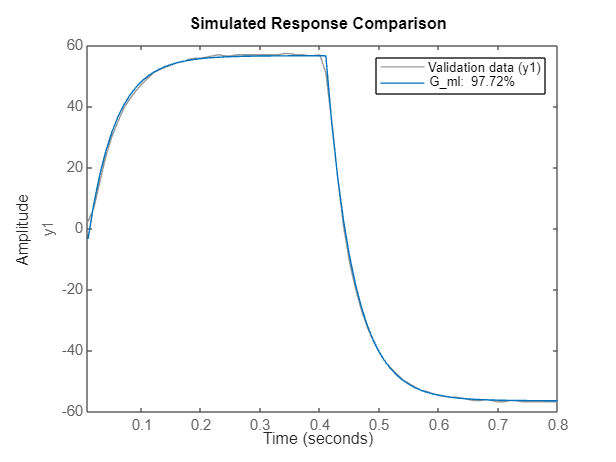

figure, compare(data_ident_ml, G_ml)

## Motor Direito

data_ident_mr = iddata(gradient(data.theta_mr, data.t), data.u_mr, ts)

data_ident_mr =

Time domain data set with 80 samples.
Sample time: 0.0100013 seconds        
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties


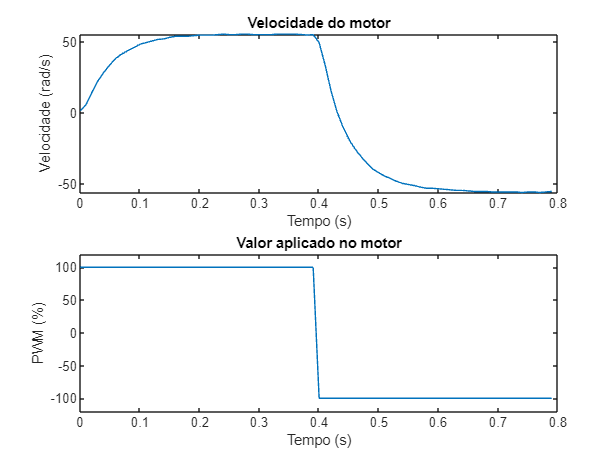

omega_mr = gradient(data.theta_mr, data.t); % velocidade ângular do motor esquerdo

figure
subplot(2,1,1)
plot(data.t, omega_mr)
title("Velocidade do motor"), xlabel("Tempo (s)"), ylabel("Velocidade (rad/s)")

subplot(2,1,2)
plot(data.t, data.u_mr)
title("Valor aplicado no motor"), xlabel("Tempo (s)"), ylabel("PWM (%)")
ylim([-120 120]), yticks(-100:50:100)

### Estimativa do modelo para o motor direito

G_mr = tfest(data_ident_mr, 1, 0)

G_mr =
 
  From input "u1" to output "y1":
   11.91
  --------
  s + 21.6
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using TFEST on time domain data "data_ident_mr".
Fit to estimation data: 97.79%                            
FPE: 1.253, MSE: 1.162                                    
 
Model Properties


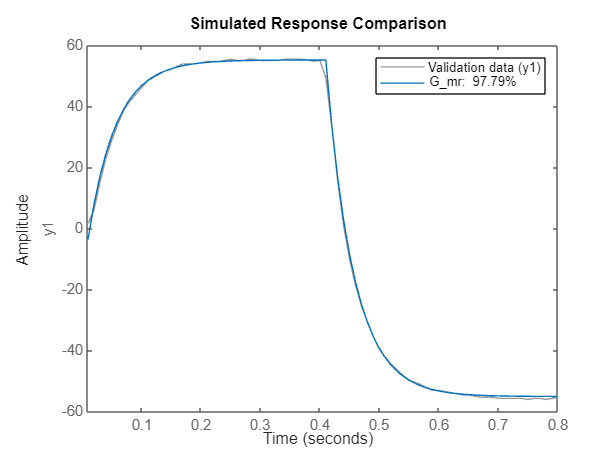

figure, compare(data_ident_mr, G_mr)

## Modelos Finais

G_ml = zpk(G_ml)

G_ml =
 
  From input "u1" to output "y1":
   12.316
  ---------
  (s+21.79)
 
Continuous-time zero/pole/gain model.
Model Properties


G_mr = zpk(G_mr)

G_mr =
 
  From input "u1" to output "y1":
   11.907
  --------
  (s+21.6)
 
Continuous-time zero/pole/gain model.
Model Properties


## Controladores

- Aqui projetaremos apenas um controlador visto que ambas as rodas possuem modelos próximos

- O motor esquerdo será utilizado no projeto:

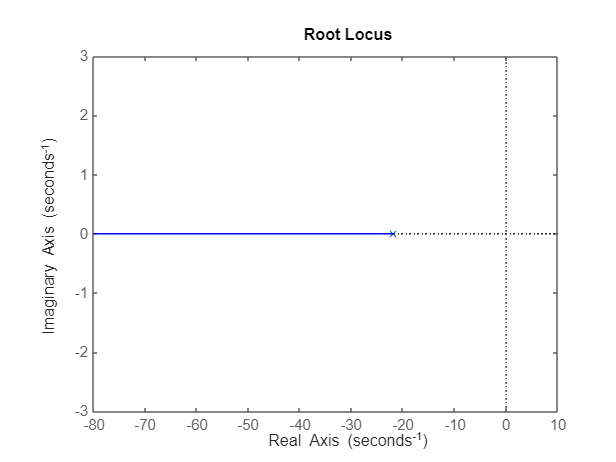

figure, rlocus(G_ml)

- Como pode ser visto, o motor é uma planta de primeira ordem, portanto, possui apenas um polo

- O lugar das raizes no gráfico acima mostra que em malha fechada qualquer ganho manterá a planta estável, portanto, vamos supor um controlador de ganho unitário:

s = tf('s');

C_ml_uni = 1

C_ml_uni = 1

G_mf = feedback(C_ml_uni*G_ml, 1)

G_mf =
 
  From input "u1" to output:
   12.316
  ---------
  (s+34.11)
 
Continuous-time zero/pole/gain model.
Model Properties


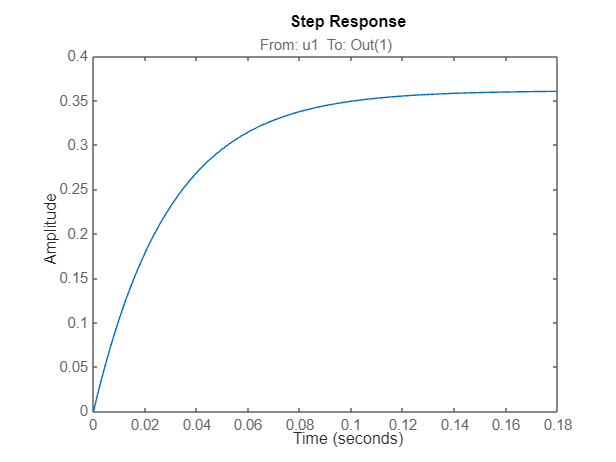

figure, step(G_mf) % degrau na referência igual a 1

- A resposta estabiliza em 0,35 mas a referência pedida foi 1, isto é longe, mas podemos melhorar utilizando um controlador com um ganho maior, mas este erro nunca será zero

- Para termos erro zero é necessário um integrador no controlador, por isto usaremos um PI

- Um controlador PI possui um zero e um polo integrador no seguinte formato:


$$C = K \frac{(s + z)}{s}$$


- Arbitrariamente escolhemos um controlador PI com um zero real em 25 pois assim o polo da planta e o polo integrador serão atraidos para uma região mais rápida (a velocidade desejada será alcançada mais rapidamente)

C_ml_PI = (s+25)/s

C_ml_PI =
 
  s + 25
  ------
    s
 
Continuous-time transfer function.
Model Properties


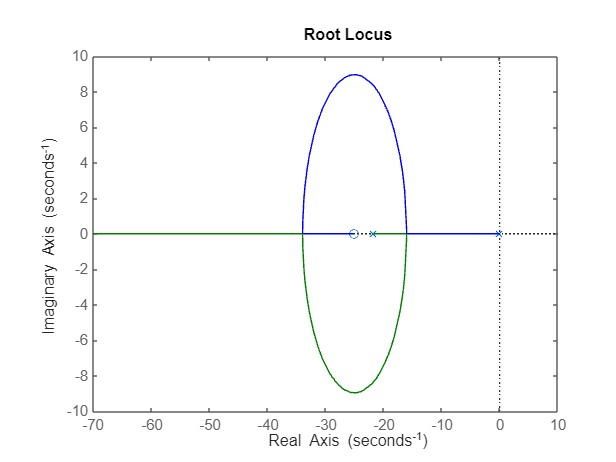

rlocus(C_ml_PI*G_ml)

- O lugar das raizes acima mostra que variando o ganho do controlador os polos iram se encontrar próximo de 15 e novamente em 35

- Não queremos oscilações na resposta em malha fechada por isso escolheremos um ganho que mantenha os polos no eixo real, 

- Além disso, para uma resposta mais rápida os polos devem estar próximo de 35, pois após se encontrarem eles irão se separar e um dos polos irá em direção ao zero em 25, deixando a dinâmica mais lenta.

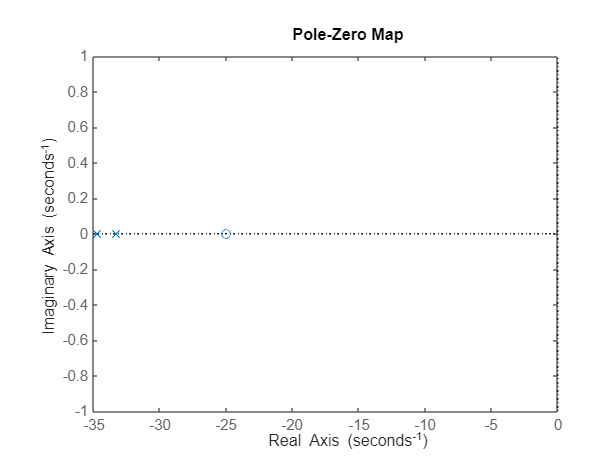

k = 3.75;
G_mf = feedback(k*C_ml_PI*G_ml, 1);

figure, pzplot(G_mf)

- Há varios métodos para projetar um controlador mas neste tutorial apenas iremos ajustar o ganho até que os polos estejam na posição de interesse: polos no eixo real e únidos

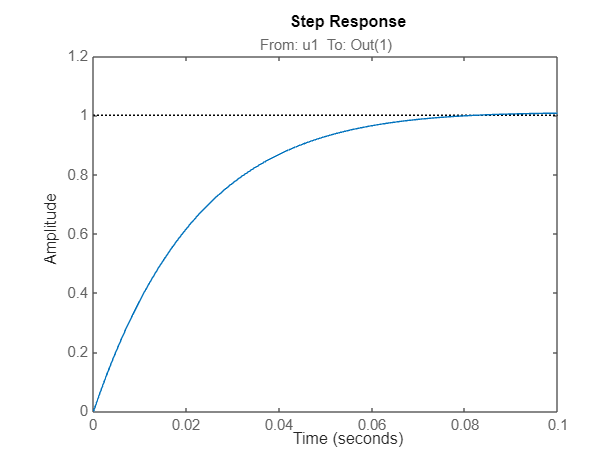

figure, step(G_mf)

- Como esperado agora temos erro nulo em regime permanente

## Implementação do Controlador

- Todo o projeto foi feito no domínio da frequência, mas na implementação real em código tudo é no tempo, logo devemos converter o controlador para um formato mais prático.

- Podemos expandir o numerador do controlador e observar seus componentes:


$$C = 3.75 \frac{(s + 25)}{s} = 3.75 \left(1 + \frac{25}{s} \right) = 3.75 \left(1 + \frac{1}{0.04s} \right)$$


- O controlador PI é composto pela soma de dois termos: um termo unitário (1) e um termo integrador $\((\frac{1}{\tau s})\)$, onde o tempo de integração ($\(\tau\)$) é 0,04. Essa soma é então multiplicada por um ganho, que neste caso é 3,75.

- Não conseguimos calcular a integral dentro de um computador por isso iremos aproximar-lá utilizando o método dos trapézios

## Dados Experimentais

data_ctrl = readtable("controle_motor_dados.txt")

data_ctrl = 2047×6 table
      t       ref    u_ml    omega_ml    u_mr    omega_mr
    ______    ___    ____    ________    ____    ________

         0     0      0         0         0         0    
      0.01     0      0         0         0         0    
      0.02     0      0         0         0         0    
      0.03     0      0         0         0         0    
      0.04     0      0         0         0         0    
      0.05     0      0         0         0         0    
      0.06     0      0         0         0         0    
      0.07     0      0         0         0         0    
      0.08     0      0         0         0         0    
      0.09     0      0         0         0         0    
       0.1     0      0         0         0         0    
    0.1101     0

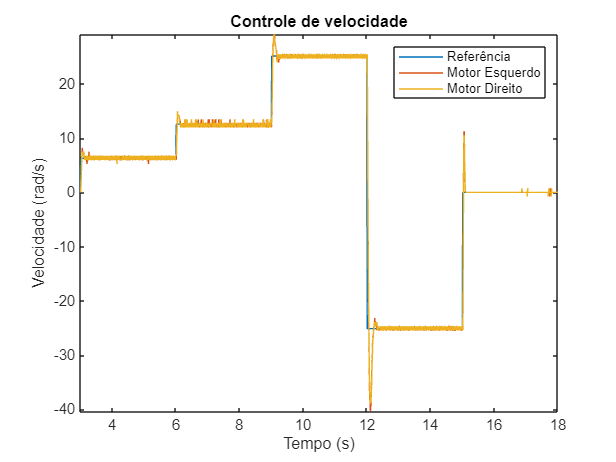

figure
plot(data_ctrl.t, data_ctrl.ref)
hold on
plot(data_ctrl.t, data_ctrl.omega_ml)
plot(data_ctrl.t, data_ctrl.omega_mr)
axis tight, xlim([3 18])
title("Controle de velocidade"), xlabel("Tempo (s)"), ylabel("Velocidade (rad/s)")
legend("Referência", "Motor Esquerdo", "Motor Direito")

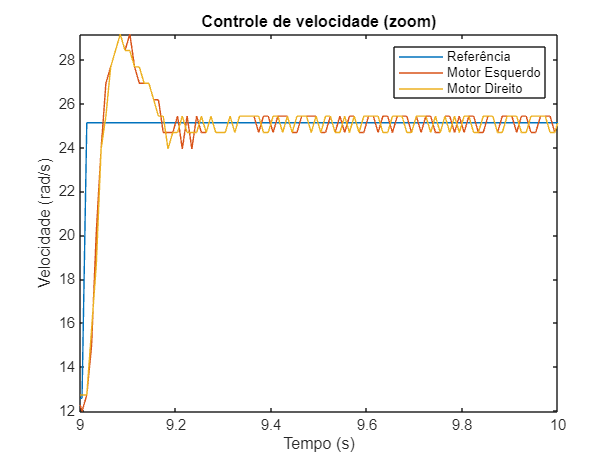

figure
plot(data_ctrl.t, data_ctrl.ref)
hold on
plot(data_ctrl.t, data_ctrl.omega_ml)
plot(data_ctrl.t, data_ctrl.omega_mr)
axis tight, xlim([9 10])
title("Controle de velocidade (zoom)"), xlabel("Tempo (s)"), ylabel("Velocidade (rad/s)")
legend("Referência", "Motor Esquerdo", "Motor Direito")

- Como pode ser visto a velocidade está controlada e segue a referencia apesar dos ruídos.

- Grande parte deles são causados pelo tempo de amostragem e o encoder digital, como pouco tempo se passa entre os cálculos não dá para coletar muitos pontos do encoder, com isso os valores de velocidade são sempre muito quantizados.

- Para consertar isso uma possíbilidade é utilizar um tempo de amostragem maior, neste experimento foi utilizado 10 milisegundos, com um tempo maior, mais pontos seriam coletados e a velocidade seria mais precisa, mas nem sempre isso é possível. 

- O motor é rápido, se utilizar um tempo de amostragem muito grande muita coisa vai acontecer antes que o controlador saiba. Você pode testar isso alterando o tempo de amostragem no código disponibilizado, chega um momento em que o motor começa a tremer o balançar sem parar.

- A segunda possiblidade é utilizar um filtro que para suavizar a leitura de velocidade ao longo do tempo. Isso é possivel porque o filtro leva em consideração o historico de medidas de velocidade, o que compensa o curto tempo de amostragem que temos. Está segundo opção será a mais utilizada neste trabalho visto que no pêndulo tudo é muito rápido, não dá para aumentar o tempo de amostragem porque demorar muito na hora de corrigir um erro provavelmente fará o pendulo cair.